## New signal

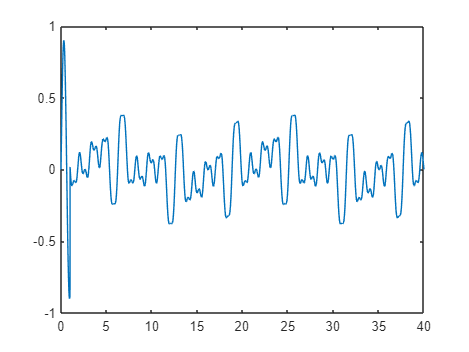

h = 0.01;
t = 0:h:40;
t1 = t(1:100);
t2 = t(101:end);
umax1 = 0.9;
umax2 = 0.16;
u = zeros(length(t),1);
u(1:100) = umax1 * sin(t1*5);
u(101:end) = umax2*(0.3 * sin(10*t2) + 0.5 * sin(t2/3) + 0.75 * sin(2*t2) + 0.9*sin(t2*4) + 0.8 * sin(t2*3));
plot(t,u)

input = timeseries(u,t);

## new signal without kick

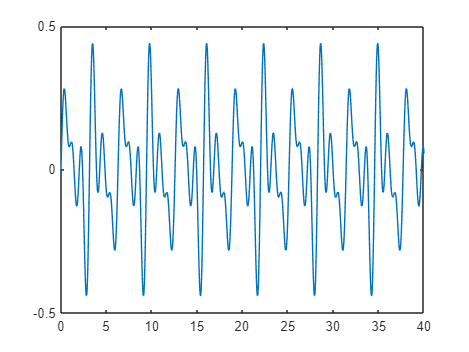

h = 0.01;
t = 0:h:40;
umax2 = 0.16;
u = zeros(length(t),1);
u = umax2*(0.3 * sin(2*t) + 0.5 * sin(t*5 + pi) + 0.75 * sin(2*t) + 0.9*sin(t*4) + 0.8 * sin(t*6));
plot(t,u)

input = timeseries(u,t);

## chirp signal

## save('signal_1_21_5.mat','u', 't', 'pendulum_angle', 'angular_velocity')

## Signal 1 - both 

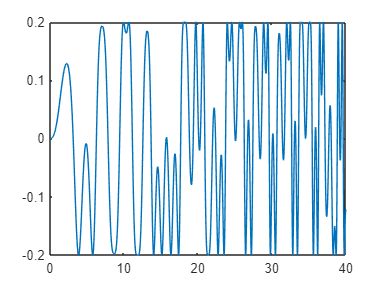

h = 0.01;
data = load("signal_1_12_5.mat");
u =  0.2 * data.u;
t = 0:h:length(u)*h-h;
input = timeseries(u,t);
plot(t,u)

## Signal 1b

data = load("signal_1b_21_5.mat");
u = 0.8 * data.u;
input = timeseries(u,t);

## Signal 2 - pendulum

t_2 = 0:h:10-h;
u = zeros(length(t_2),1);
input = timeseries(u,t_2);
% data = load("signal_2_21_5.mat");
% u = data.u;
% input = timeseries(u,t);

## Signal 2b

data = load("signal_2b_12_5.mat");

Error using load
'signal_2b_12_5.mat' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\jhines\Documents\Integration Project 1

Change the MATLAB current folder or add its folder to the MATLAB path.

u = data.u;
input = timeseries(u,t);

## Signal 3 - flywheel

data = load("signal_3_12_5.mat");

Error using load
Unable to find file or directory 'signal_3_21_5.mat'.

u = data.u;
input = timeseries(u,t);

## Signal 3b

data = load("signal_3_12_5.mat");
u = data.u;
input = timeseries(u,t);

## PRBS

T_clock = 8*h;
N_bits = 8;
N_reps = 2;

prbs = idinput(2^N_bits - 1, 'prbs', [0,1/(T_clock/h)], [-1,1]);

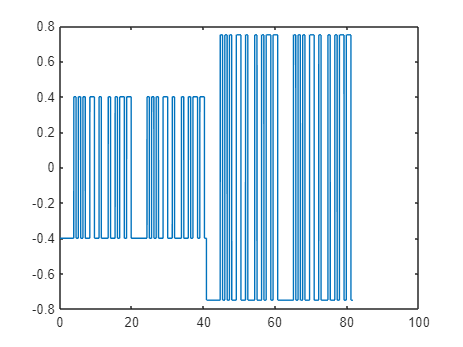

prbs_unsampled = repelem(prbs, T_clock/h);

u = [];
amplitudes = [00.4 0.75];

for a = amplitudes
    
    seg = a * prbs_unsampled;
    u = [u; repmat(seg, N_reps, 1)];

end

t = 0:h:h*(length(u)-1);
input = timeseries(u',t);
plot(t,u)

## Multisine 2

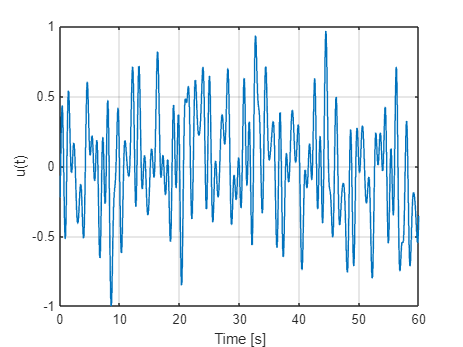

T = 10;
t0 = (0:h:T-h)';

freqs  = 0.1:0.5:7.5;
phases = 2*pi*rand(size(freqs));

% Generate multisine
u0 = sum(sin(2*pi*freqs'.*t0' + phases'),1)';

% Normalize
u0 = u0 / max(abs(u0));

% Stretch factor
Nhold = 6;

% Hold each sample for Nhold timesteps
u = repelem(u0, Nhold);

% New time vector
t = (0:length(u)-1)' * h;

% Timeseries
input = timeseries(u, t);

% Plot
figure;
plot(t,u)
xlabel('Time [s]')
ylabel('u(t)')
grid on